# 二項分布とポアソン分布

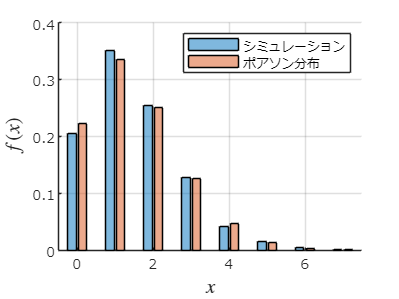

clear;clc;close all;

lambda=1.5;
n=1000;
M=2000;

p=lambda/n;
c=zeros(M,1);
for n1=1:M
    for n2=1:n
        if rand()<p
            c(n1)=c(n1)+1;
        end
    end
end

f=histcounts(c,0:n)/M;
x=0:5*lambda;
f_poiss=poisspdf(x,lambda);
figure;
grid on;hold on;set(gca,'fontname','メイリオ')
bar(x,[f(1:size(x,2));f_poiss],'FaceAlpha',0.5);
xlabel('$x$','Interpreter','latex','FontSize',12);
ylabel('$f(x)$','Interpreter','latex','FontSize',12);
legend({'シミュレーション','ポアソン分布'});
exportgraphics(gcf,'fig_poiss-bin.pdf');